clear all
close all
clc

rng('default');

datasize = 3000;
inz = smoothdata(rand(datasize,1),'gaussian',5);

% plot(inz)
% 
% FY = mag2db(abs(fft(inz)));
% 
% figure;
% hold on
% plot(FY(1:floor(end/2)))
% hold off



% Choose parameters
% rng(2)
n=2; m=2;
mn = n+m;

inlags=[1 2 3 4];
outlags =[0 1 2 3 4];

d=numel(inlags)+numel(outlags)-1;

maxranksynth =5;
rk = (min(min(mn.^[0:d],mn.^[d:-1:0]),maxranksynth));

scale = 9;
synth = 0.5+ scale*(double(rand(mn*ones(1,d))>0.5)-0.5);

TN = trunttsvd(synth,rk)

TN = struct with fields:
    core: {[1×4×4 double]  [4×4×5 double]  [5×4×5 double]  [5×4×5 double]  [5×4×5 double]  [5×4×5 double]  [5×4×4 double]  [4×4 double]}
      sz: [8×3 double]



norm(TN.core{end})

ans = 137.1025

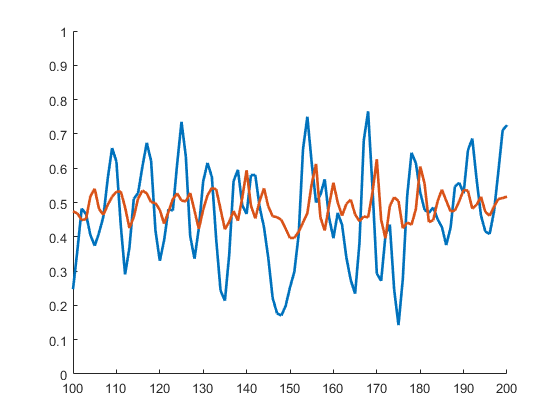


% siminput(1:21)=heaviside(-10:10)/2;
siminput = inz;
simoutput = zeros(datasize,1);

% siminput = 1*ones(1000,1);
% siminput = 0.2*sin(1:0.01:11)'+0.5;

for j = 10:datasize
simfeaturez = [simoutput(j-outlags(2:end))' siminput(j-inlags(1:end))'];
% simfeaturez(simfeaturez<0)=0;
% simfeaturez(simfeaturez>1)=1;
simoutput(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
plot(siminput,'Linewidth',2)
plot(simoutput,'Linewidth',2)
% plot((inz(11)/simoutput(11))*simoutput)
hold off
axis([100 200 0 1])

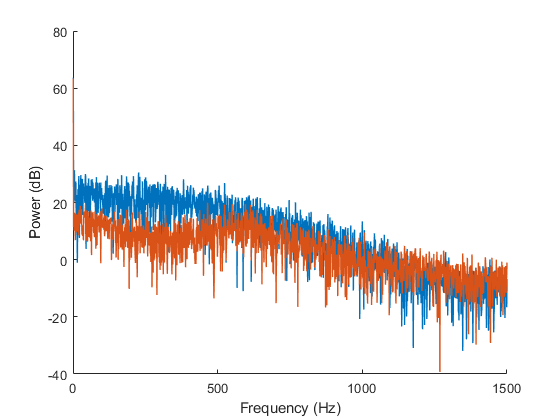


FX = mag2db(abs(fft(siminput)));
FY = mag2db(abs(fft(simoutput)));
figure;
hold on
plot(FX(1:floor(end/2)),'Linewidth',1)
plot(FY(1:floor(end/2)),'Linewidth',1)
hold off
xlabel('Frequency (Hz)')
ylabel('Power (dB)')

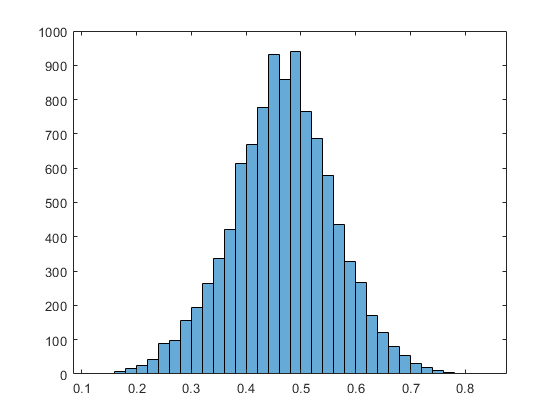


testfeatures = rand(10000,8);
testput = evalspline(TN,testfeatures,n,m);
histogram(testput')


figure;
hold on
plot(simoutput,'Linewidth',3, "Color",[0 0 1])

SNR = [10 0 -10]

SNR =     10     0   -10


colr = flipud(0.7*eye(3)+0.3)

colr =     0.3000    0.3000    1.0000
    0.3000    1.0000    0.3000
    1.0000    0.3000    0.3000


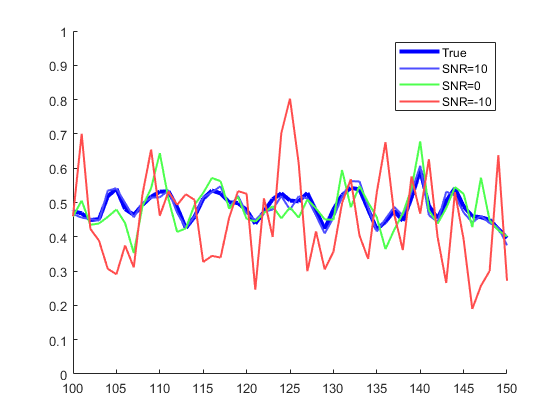

for period = 1:numel(SNR)

plotnoise = addnoise(simoutput,SNR(period));
plot(plotnoise,'Linewidth',1.5, "Color",colr(period,:))
end
hold off
axis([100 150 0 1])

legend('True', 'SNR=10','SNR=0','SNR=-10')

SNR = [30 25 20 15 10 5 0 -5 -10 -15]

SNR =     30    25    20    15    10     5     0    -5   -10   -15


SNR = [0]

SNR = 0

for period = 1:numel(SNR)

simoutputnoise = addnoise(simoutput,SNR(period));
% snr(simoutput,simoutputnoise-simoutput)


% simoutputnoise(simoutputnoise>1) = 1;
% simoutputnoise(simoutputnoise<0) = 0;

% figure
% hold on
% % plot(siminput)
% plot(simoutput,'Linewidth',2)
% plot(simoutputnoise)
% % plot((inz(11)/simoutput(11))*simoutput)
% hold off
% axis([0 200 -inf inf])



input = siminput(10:2000);
output = simoutputnoise(10:2000);

tinput = siminput(2001:end);
toutput = simoutput(2001:end);
toutputnoise = simoutputnoise(2001:end);


Preprocessing Data

tic

% Choose the lags for the input
inlags=[1 2 3 4];
for l = 1:length(inlags)
u(:,l) = input(end-inlags(l)-(1900):end-inlags(l));
uv(:,l) = tinput(end-inlags(l)-(900):end-inlags(l));
end

% Choose the lags for the output, 0 is the estimated output
outlags=[0 1 2 3 4];
for l = 1:length(outlags)
y(:,l) = output(end-outlags(l)-(1900):end-outlags(l));
yv(:,l) = toutput(end-outlags(l)-(900):end-outlags(l));
end



Split test and training set

featurez = [y(:,2:end)  u];
zeta = y(:,1);

tfeaturez = [yv(:,2:end)  uv];
yt = yv(:,1);


Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 2;                  %degree B-spline
m = 2;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);




Initialize tensor train -----------------------------------------------------------------

% Choose TT-ranks
maxrank =5;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

for trial = 1:3

[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


% Pcount = (In)^d;                    %Original tensor size
% dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
% disp(['Compression: ' num2str(dof/Pcount)]);  %ratio


Optimize TT cores

% lambda=1*10^-8;
LAMBDA = [10^-4 10^-8];

for nmr = 1:2
lambda= LAMBDA(nmr);

difforder=2;
MAXITR = 2*d;


% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);


% MAXITR = d;
nselect = ones([1,MAXITR])*N;
% plot(nselect)

[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,difforder);

% 
% plot(res1)
% plot(res2)
% 
% trainerror = res1(end)

% plot(rez)

Evaluate Test data

% 
% yhattrain  = evalspline(TN,featurez,n,m);
% 
% figure;
% hold on
% % plot(zeta)
% plot(outputclean(end-1900:end))
% plot(yhattrain)
% hold off
% axis([0 inf -inf inf]);
% 
% erboiz = (yhattrain-zeta);
% VAF = 1-var(erboiz)/var(zeta)
% MSE = immse(yhattrain,zeta)



% 
yhat = evalspline(TN,tfeaturez,n,m);
% erboi = (yhat-yt);
% histogram((erboi)');
% VAF = 1-var(erboi)/var(yt)
% MSE = immse(yhat,yt)

RMSE_P(period,nmr,trial) = sqrt(immse(yhat,yt));

% figure
% hold on
% plot(yt)
% plot(yhat)
% hold off
% axis([0 200 -inf inf])
% 
% %  Visualize errors
% [sortout,Iss]=sort(yhat);
% figure
% hold on
% plot(yt(Iss))
% plot(sortout,'Linewidth',3)
% hold off
% 
% FY = mag2db(abs(fft(yhat)));
% FZ = mag2db(abs(fft(yt)));
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off


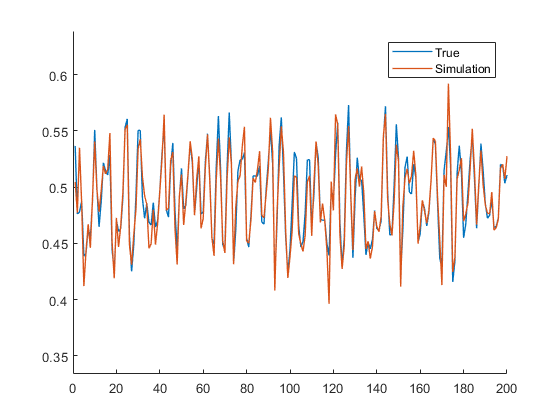

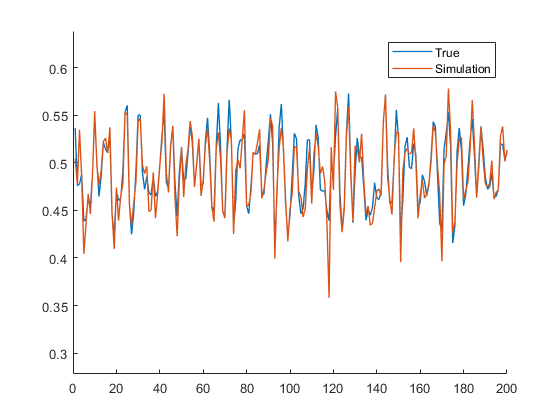

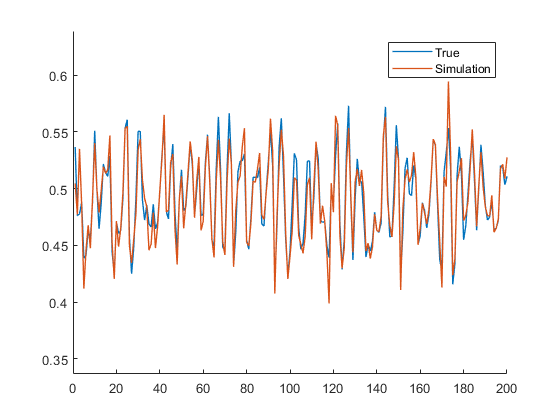

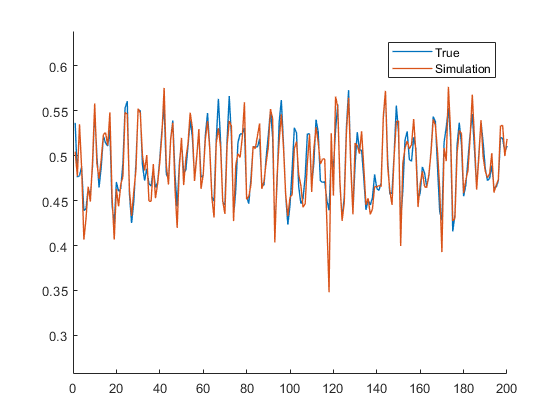

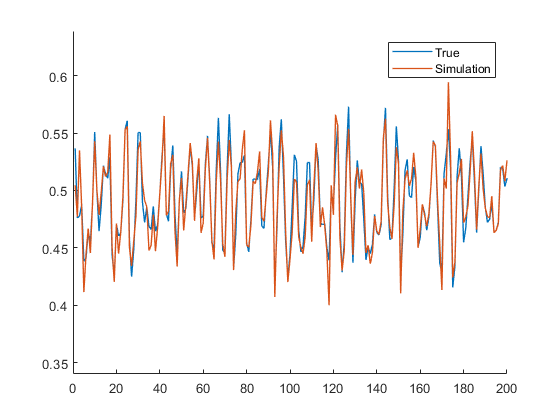

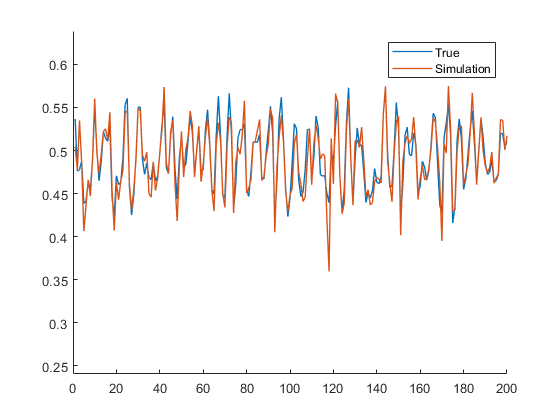

% plot(tinput)
% plot(toutput)

siminputz = tinput;
simoutputz = toutputnoise(1:outlags(end));
numz = numel(outlags);
for j = (outlags(end)+1):1000
simfeaturez = [simoutputz(j-outlags(2:end))' siminputz(j-outlags(2:end))'];
simfeaturez(simfeaturez<0)=0;
simfeaturez(simfeaturez>1)=1;
simoutputz(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
% plot(toutputnoise)
plot(toutput,'Linewidth',1)
plot(simoutputz,'Linewidth',1)
hold off
legend('True', 'Simulation')
axis([0 200 -inf inf])


RMSE_S(period,nmr,trial) = sqrt(immse(toutput,simoutputz));
% MAPE(period) = mean(abs(toutput-simoutputz)./abs(toutput))
% RMSRE(period) = sqrt(sum((toutput-simoutputz).^2)/sum(toutput.^2))
% RRMSE(period) = sqrt((immse(toutput,simoutputz))/sum(toutput.^2))
% VAF(period) = 1-var(toutput-simoutputz)/var(toutput)
% RLOG(period) = mean(log(simoutputz./toutput))

toc

Elapsed time is 1.054423 seconds.


Elapsed time is 0.940583 seconds.


Elapsed time is 0.758202 seconds.


Elapsed time is 0.843831 seconds.


Elapsed time is 0.728563 seconds.


Elapsed time is 0.748555 seconds.


end
end
end

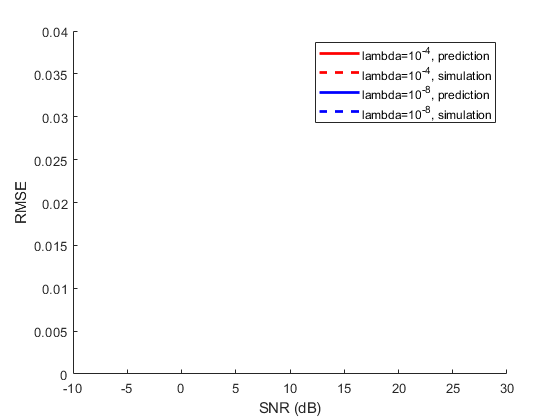

figure;

RMSE_Plot = mean(RMSE_P,3);
RMSE_Slot = mean(RMSE_S,3);

hold on
plot(SNR,RMSE_Plot(:,1),'Linewidth',2,"Color",'r')
plot(SNR,RMSE_Slot(:,1),'Linewidth',2,"Color",'r',"LineStyle","--")
plot(SNR,RMSE_Plot(:,2),'Linewidth',2,"Color",'b')
plot(SNR,RMSE_Slot(:,2),'Linewidth',2,"LineStyle","--","Color",'b')
% plot(SNR,RMSE_Slot(:,2))
hold off
xlabel('SNR (dB)')
ylabel('RMSE')
legend('lambda=10^{-4}, prediction', 'lambda=10^{-4}, simulation','lambda=10^{-8}, prediction','lambda=10^{-8}, simulation')
axis([-10 30 0 0.04])

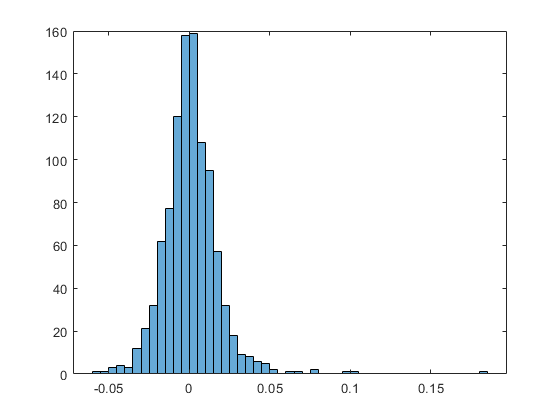



histogram(toutput-simoutputz)